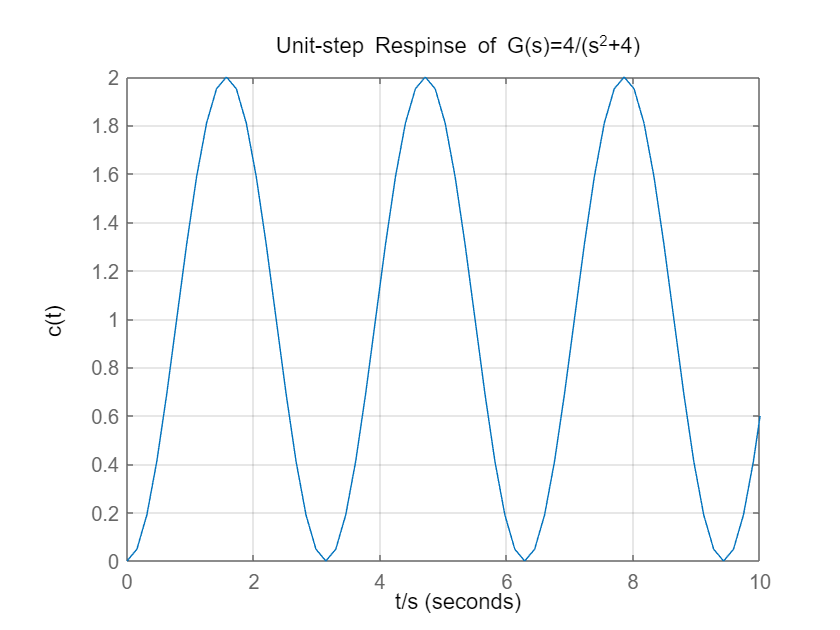

% wn=2，阻尼比为0——震荡
num=[0 0 4]; %定义分子多项式
den=[1 0 4]; %定义分母多项式
sys= tf(num,den); %写出系统的传递函数
step(sys) %调用阶跃响应函数，也可以直接用 step(num,den)
grid %画网格标度线
xlabel('t/s'),ylabel('c(t)') ; %给坐标轴加上说明
xlim([0 10]);
title('Unit-step Respinse of G(s)=4/(s^2+4)') ; %给图形加上标题名

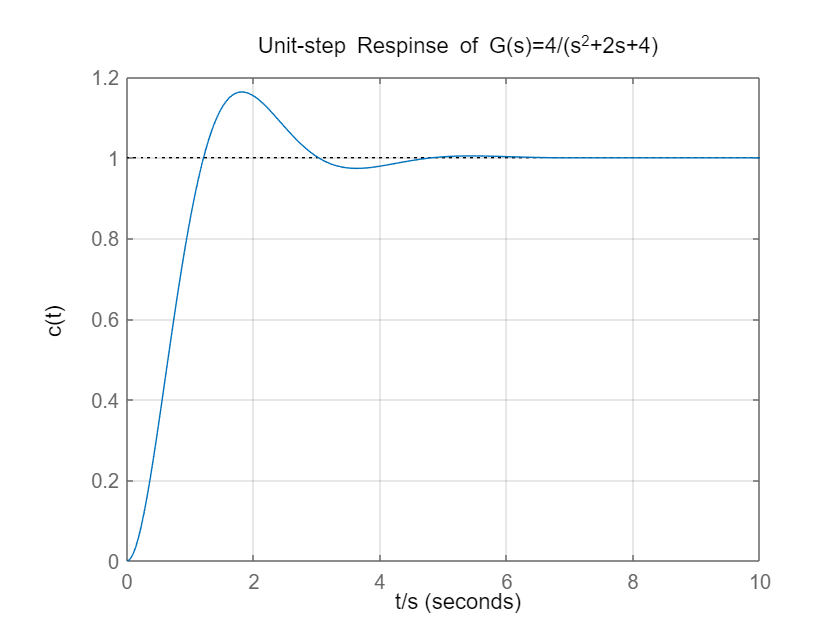

% wn=2，阻尼比为0.5——欠阻尼，有超调
num=[0 0 4]; %定义分子多项式
den=[1 2 4]; %定义分母多项式
sys= tf(num,den); %写出系统的传递函数
step(sys) %调用阶跃响应函数，也可以直接用 step(num,den)
grid %画网格标度线
xlabel('t/s'),ylabel('c(t)') ; %给坐标轴加上说明
xlim([0 10]);
title('Unit-step Respinse of G(s)=4/(s^2+2s+4)') ; %给图形加上标题名

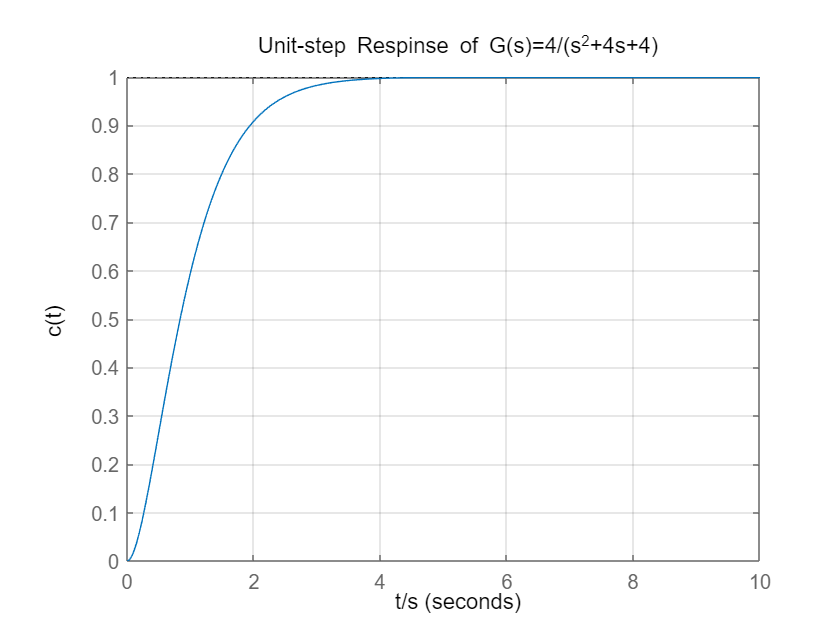

% wn=2，阻尼比为1.0——临界阻尼
num=[0 0 4]; %定义分子多项式
den=[1 4 4]; %定义分母多项式
sys= tf(num,den); %写出系统的传递函数
step(sys) %调用阶跃响应函数，也可以直接用 step(num,den)
grid %画网格标度线
xlabel('t/s'),ylabel('c(t)') ; %给坐标轴加上说明
xlim([0 10]);
title('Unit-step Respinse of G(s)=4/(s^2+4s+4)') ; %给图形加上标题名

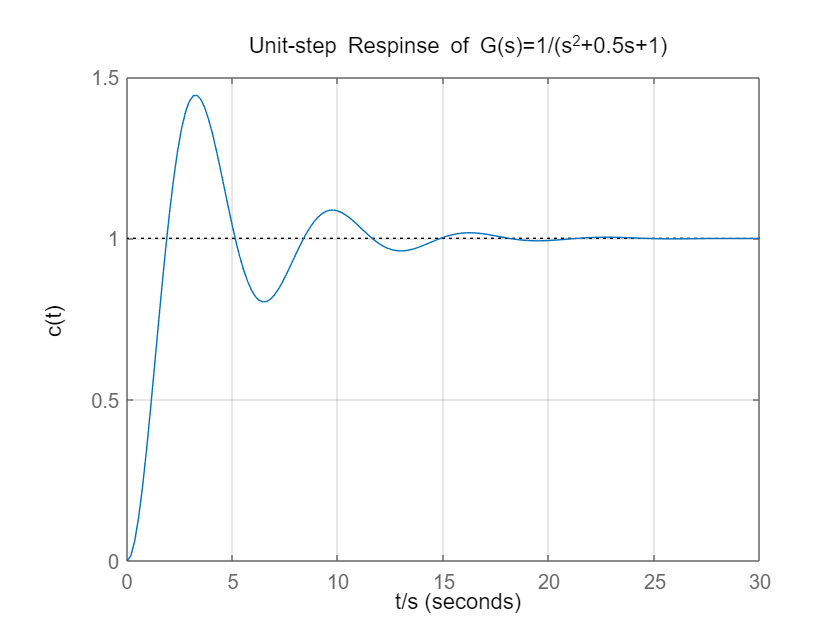

% 阻尼比为0.25，wn=1
num=[0 0 1]; %定义分子多项式
den=[1 0.5 1]; %定义分母多项式
sys= tf(num,den); %写出系统的传递函数
step(sys) %调用阶跃响应函数，也可以直接用 step(num,den)
grid %画网格标度线
xlabel('t/s'),ylabel('c(t)') ; %给坐标轴加上说明
xlim([0 30]);
title('Unit-step Respinse of G(s)=1/(s^2+0.5s+1)') ; %给图形加上标题名

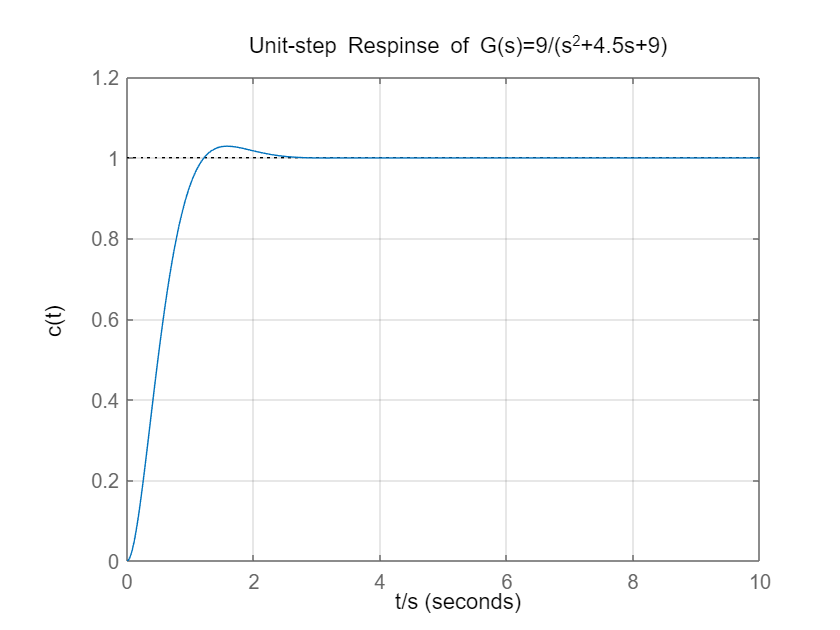

% 阻尼比为0.25，wn=3
num=[0 0 9]; %定义分子多项式
den=[1 4.5 9]; %定义分母多项式
sys= tf(num,den); %写出系统的传递函数
step(sys) %调用阶跃响应函数，也可以直接用 step(num,den)
grid %画网格标度线
xlabel('t/s'),ylabel('c(t)') ; %给坐标轴加上说明
xlim([0 10]);
title('Unit-step Respinse of G(s)=9/(s^2+4.5s+9)') ; %给图形加上标题名

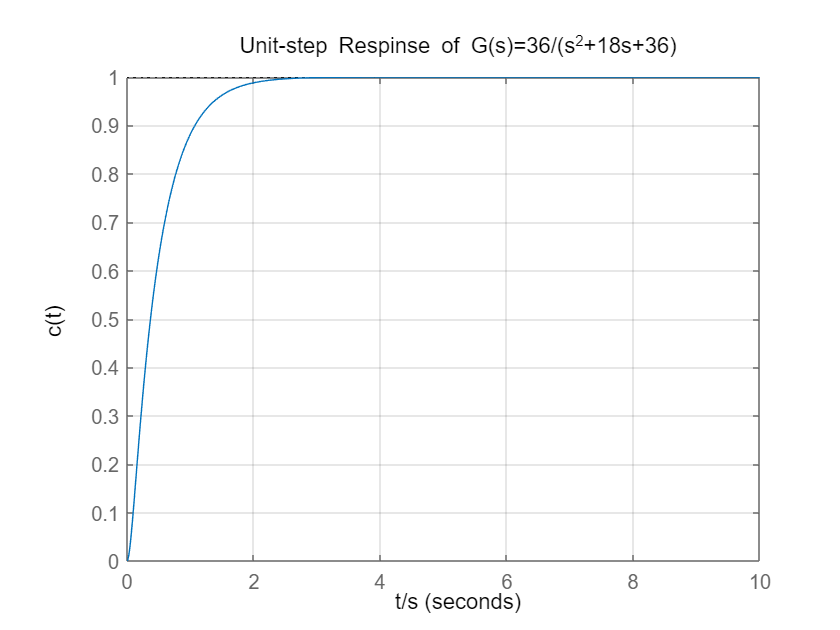

% 阻尼比为0.25，wn=6
num=[0 0 36]; %定义分子多项式
den=[1 18 36]; %定义分母多项式
sys= tf(num,den); %写出系统的传递函数
step(sys) %调用阶跃响应函数，也可以直接用 step(num,den)
grid %画网格标度线
xlabel('t/s'),ylabel('c(t)') ; %给坐标轴加上说明
xlim([0 10]);
title('Unit-step Respinse of G(s)=36/(s^2+18s+36)') ; %给图形加上标题名

% 直接求根判稳——不稳定（有两个根不在左半平面）
roots([2,1,3,5,10])

ans =    0.7555 + 1.4444i
   0.7555 - 1.4444i
  -1.0055 + 0.9331i
  -1.0055 - 0.9331i


% 劳斯判据——不稳定（符号变换了两次）
syms EPS %定义符号
den=[2,1,3,5,10];
ra=routh(den,EPS)

$$ra = \left(\begin{array}{ccc} 2 & 3 & 10\\ 1 & 5 & 0\\ -7 & 10 & 0\\ \frac{45}{7} & 0 & 0\\ 10 & 0 & 0 \end{array}\right)$$